# Furuta Pendulum - State Space

## 1. Load the Nonlinear Model

The previous file derived M, h and G. Use them here to find a small-signal model around equilibrium.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
assert(isfile('data/Nonlinear_Model.mat'),'Run the Mathematical Model first.');
load('data/Nonlinear_Model.mat');


## 2. Equilibrium Points

At equilibrium, both velocities are zero and the pendulum gravity torque is zero. Check upright and downward positions. This is stability analysis, not a swing-up controller.

pendulum_gravity = @(a) [0 1]*G_fun([0;a]);
q_up = [0; fzero(pendulum_gravity,0)];
q_down = [0; fzero(pendulum_gravity,pi)];
x_equilibrium = [q_up;0;0];
tau_equilibrium = [1 0]*G_fun(q_up);
equilibrium_angles = table(q_up,q_down)

equilibrium_angles = 2×2 table
      q_up       q_down
    _________    ______

            0         0
    3.174e-05    3.1416


equilibrium_residual = G_fun(q_up) - [tau_equilibrium;0]

equilibrium_residual = 1.0e-18 *

         0
   -0.1280


## 3. Linearized Mechanical Equations

Near equilibrium: M0 delta_qdd + D delta_qd + K0 delta_q = [delta_tau;0]. K0 is the derivative of gravity torque with respect to the angles.

gravity_jacobian = jacobian(G_sym,q);
M0 = M_fun(q_up)

M0 = 1.0e-03 *

    0.1553   -0.0082
   -0.0082    0.0116


K0 = double(subs(gravity_jacobian,q,q_up))

K0 =     0.0000   -0.0000
   -0.0000   -0.0016


D0 = D_mech

D0 = 1.0e-03 *

    0.5730         0
         0    0.0315


## 4. State-Space Matrices

State order: arm angle, pendulum angle, arm velocity, pendulum velocity. The output y contains the two measured angles.

A = [zeros(2),eye(2); -M0\K0,-M0\D0]

A =          0         0    1.0000         0
         0         0         0    1.0000
   -0.0000    7.4894   -3.8338   -0.1496
    0.0000  141.7525   -2.7194   -2.8308


B = [zeros(2,1); M0\[1;0]]

B = 1.0e+03 *

         0
         0
    6.6912
    4.7462


C = [eye(2),zeros(2)]

C =      1     0     0     0
     0     1     0     0


D = zeros(2,1)

D =      0
     0


system = ss(A,B,C,D);


## 5. Stability, Controllability and Observability

A positive real pole means upright is unstable. The pole near zero represents the free arm-position direction. A tiny negative value from rounding does not prove full asymptotic stability.

upright_poles = eig(A)

upright_poles =    -0.0000
   10.5276
  -13.5161
   -3.6761


controllability_rank = rank(ctrb(A,B))

controllability_rank = 4

observability_rank = rank(obsv(A,C))

observability_rank = 4

Md = M_fun(q_down);
Kd = double(subs(gravity_jacobian,q,q_down));
A_down = [zeros(2),eye(2); -Md\Kd,-Md\D_mech];
downward_poles = eig(A_down)

downward_poles =   -0.0000 + 0.0000i
  -1.4805 +11.7915i
  -1.4805 -11.7915i
  -3.7037 + 0.0000i


assert(controllability_rank == 4 && observability_rank == 4);


## 6. Transfer Functions

G(s) = C(sI-A)^(-1)B+D. This relation describes small deviations from equilibrium with zero initial conditions.

transfer_functions = tf(system)


transfer_functions =
 
  From input to output...
                6691 s^2 + 1.823e04 s - 9.13e05
   1:  -------------------------------------------------
       s^4 + 6.665 s^3 - 131.3 s^2 - 523.1 s - 6.783e-10
 
              4746 s^2 - 1.165e-11 s + 4.213e-07
   2:  -------------------------------------------------
       s^4 + 6.665 s^3 - 131.3 s^2 - 523.1 s - 6.783e-10
 
Continuous-time transfer function.


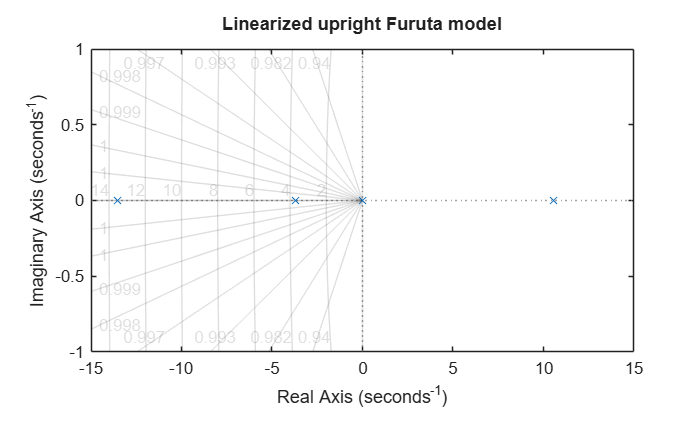

figure('Name','Upright poles and zeros','Color','w');
pzmap(system); grid on;
title('Linearized upright Furuta model');
drawnow; exportgraphics(gcf,'results/State_Space_Poles.png','Resolution',140);

## 7. Save the Linear Model

Save A, B, C, D and the equilibrium in one place. All three controllers read this same file. There is no second copy of the matrices in another folder.

save('data/Linear_Model_Data.mat','A','B','C','D','x_equilibrium','tau_equilibrium');
save('results/State_Space_Analysis.mat','upright_poles','downward_poles', ...
    'controllability_rank','observability_rank','equilibrium_residual');
